#### AERO50003

#### Introduction to Numerical Methods for ODEs and PDEs

### **Tutorial Sheet 4**

## Partial Differential Equations (PDEs)

Masoud Seifikar

Autumn Term 2023

Department of Aeronautics, Imperial College London 

### Part I: Practical Exercises

#### Exercise 1 (Wave equation)

Consider the 1st order wave equation, which is described by the partial differential equation(PDE)

∂u / ∂t + c ∂u / ∂x = 0 ,

for 0 ≤ x ≤ L and t ≥ 0 and with boundary conditions u(0, t) = 0 and

u(x, 0) = exp(−200(x − 0.2)2) .

Let c = 1 and L = 1.

1. By performing a semi-discretisation with a uniform spacing Δx, using 2nd order central differencing, show that you can approximate the PDE by a system of ordinary differential equations (ODEs) of the form

d¯u / dt = − ( c / 2Δx ) B[−1, 0, 1]¯u

where ¯u is a vector of the values of u(x, t) at each point in the spatial discretisation,

i.e. ¯u = [u1, u2, . . . , uN−1]⊤ and B[·, ·, ·] denotes a banded (tridiagonal) matrix.

% See written one

2. What is the initial condition of the ODE obtained in part 1 of this exercise?

% u(0) = exp(-200 * (x - 0.2) ^ 2)

3. Let Δx = 0.01. Using a time step Δt = 0.01 (Δt is what we denoted as h in the context of ODEs), use explicit Euler to obtain a numerical solution of the PDE.

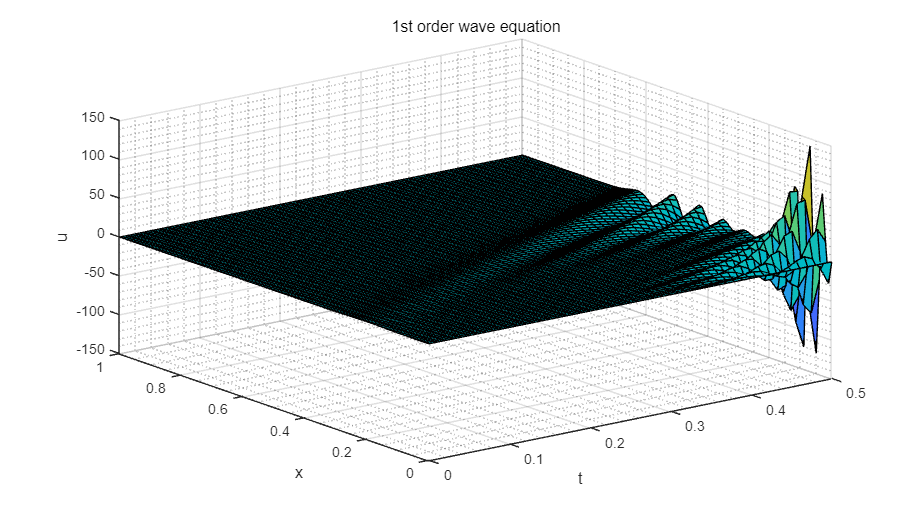

% Housekeeping
clear
clc
close all

% Define the basic parameters
c = 1;
L = 1;

t0 = 0;   % define the initial time
tf = 0.5; % define the final time

x0 = 0;                   % define the initial x
xf = L;                   % define the final x
detx = 0.01;              % Δx
N = (xf - x0) / detx + 1; % number of discretised points
X = 0: detx: L;           % define X

h = 0.01; % define the stepsize

% Define initial condition
u0 = exp(-200 * (X - .2) .^ 2);

u0(1) = 0;

% Define the function

f = @(t, u) [0; -(c / (2 * detx)) * gallery('tridiag', N - 1, -1, 0, 1) * u(2: end)]; % u(1) = 0, from u(2) to u(N-1)

% Compute the numerical solution
u = zeros(length(X), length(t0: h: tf)); % create empty matrix to store data
u(:, 1) = u0;                            % input initial condition

[t, u] = ExplicitEuler(f, t0, tf, u0', h);

% Plot the numerical solutions for angular velocity
surf(t, X, u);  % plot function

title('1st order wave equation', FontSize = 15);

xlabel('t'); 
ylabel('x');
zlabel('u');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph
set(gcf, 'Position', [0 0 1920 1080]); % show plot with larger size

4. Let Δx = 0.05. Using a time step Δt = 0.01, use explicit Euler to obtain a numerical solution of the PDE. Comment on the result with respect to the numerical solution obtained in part 3 of this question.

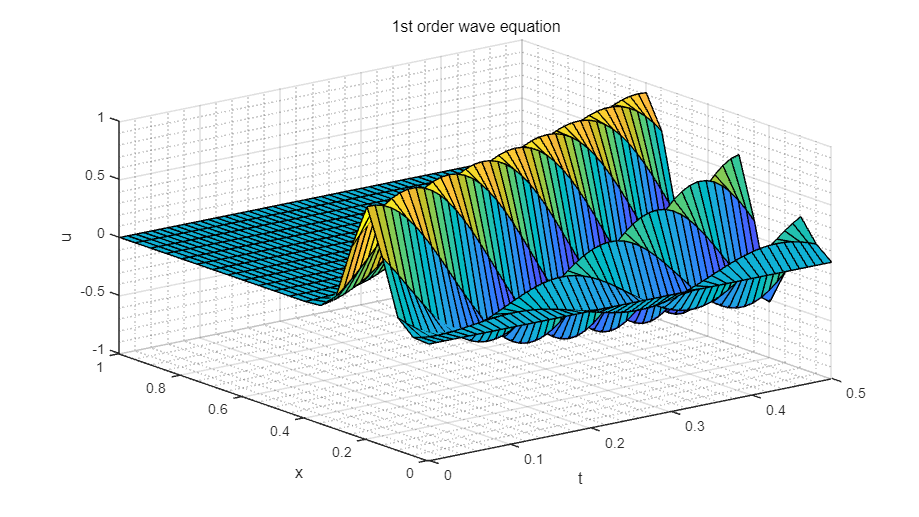

% Housekeeping
clear
clc

% Define the basic parameters
c = 1;
L = 1;

t0 = 0;   % define the initial time
tf = 0.5; % define the final time

x0 = 0;                   % define the initial x
xf = L;                   % define the final x
detx = 0.05;              % Δx
N = (xf - x0) / detx + 1; % number of discretised points
X = 0: detx: L;           % define X

h = 0.01; % define the stepsize

% Define initial condition
u0 = exp(-200 * (X - 0.2) .^ 2);

% Define the function
f = @(t, u) [0; -c / (2 * detx) * gallery('tridiag', N-1, -1, 0, 1) * u(2: end)]; % u(1) = 0, from u(2) to u(N-1)

% Compute the numerical solution
u = zeros(length(X), length(t0: h: tf)); % create empty matrix to store data
u(:, 1) = u0;                            % input initial condition

[t, u] = ExplicitEuler(f, t0, tf, u0, h);

% Plot the numerical solutions for angular velocity
surf(t, X, u);  % plot function

title('1st order wave equation', FontSize = 15);

xlabel('t'); 
ylabel('x');
zlabel('u');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph

5. Let Δx = 0.002. Try to obtain a numerical solution using explicit Euler for the time-advancement scheme, using time step a time step Δt = 0.01. What do you observe?

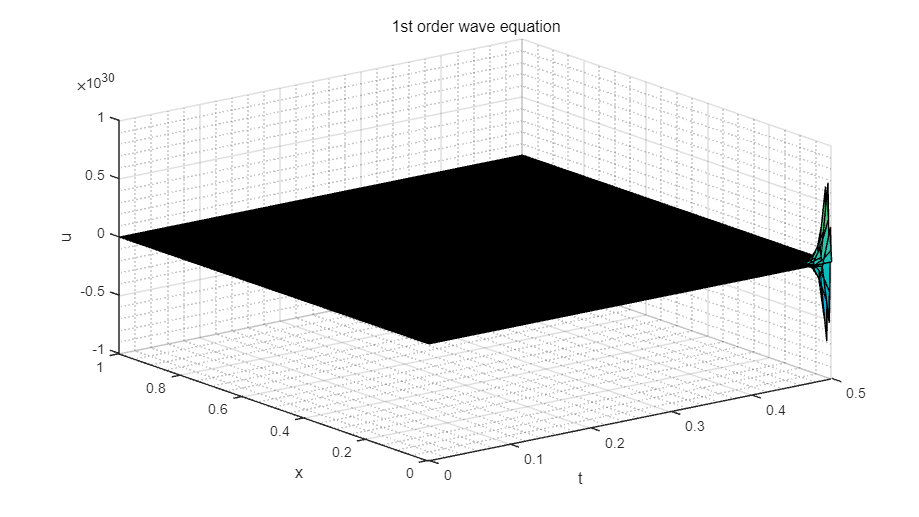

% Housekeeping
clear
clc

% Define the basic parameters
c = 1;
L = 1;

t0 = 0;   % define the initial time
tf = 0.5; % define the final time

x0 = 0;                   % define the initial x
xf = L;                   % define the final x
detx = 0.002;             % Δx
N = (xf - x0) / detx + 1; % number of discretised points
X = 0: detx: L;           % define X

h = 0.01; % define the stepsize

% Define initial condition
u0 = exp(-200 * (X - 0.2) .^ 2);

% Define the function
f = @(t, u) [0; -c / (2 * detx) * gallery('tridiag', N-1, -1, 0, 1) * u(2: end)]; % u(1) = 0, from u(2) to u(N-1)

% Compute the numerical solution
u = zeros(length(X), length(t0: h: tf)); % create empty matrix to store data
u(:, 1) = u0;                            % input initial condition

[t, u] = ExplicitEuler(f, t0, tf, u0, h);

% Plot the numerical solutions for angular velocity
surf(t, X, u);  % plot function

title('1st order wave equation', FontSize = 15);

xlabel('t'); 
ylabel('x');
zlabel('u');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph

6. Let Δx = 0.002. Obtain a numerical solution using implicit Euler for the timeadvancement scheme, using time step a time step Δt = 0.005. Comment on what you observe.

% Housekeeping
clear
clc

% Define the basic parameters
c = 1;
L = 1;

t0 = 0;   % define the initial time
tf = 0.5; % define the final time

x0 = 0;                   % define the initial x
xf = L;                   % define the final x
detx = 0.002;             % Δx
N = (xf - x0) / detx + 1; % number of discretised points
X = 0: detx: L;           % define X

h = 0.01; % define the stepsize

% Define initial condition
u0 = exp(-200 * (X - 0.2) .^ 2);

% Define the function
f = @(t, u) [0; -c / (2 * detx) * gallery('tridiag', N-1, -1, 0, 1) * u(2: end)]; % u(1) = 0, from u(2) to u(N-1)

% Compute the numerical solution
u = zeros(length(X), length(t0: h: tf)); % create empty matrix to store data
u(:, 1) = u0;                            % input initial condition

[t, u] = ImplicitEuler(f, t0, tf, u0, h);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

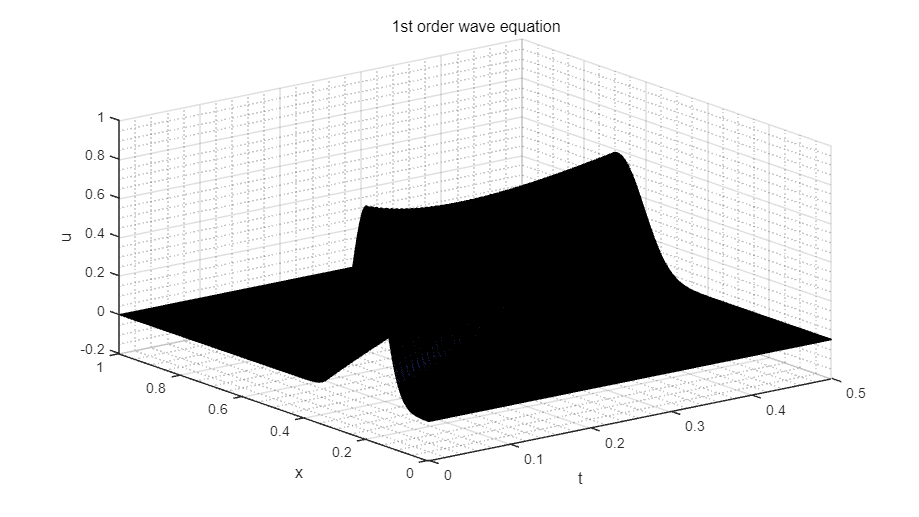


% Plot the numerical solutions for angular velocity
surf(t, X, u);  % plot function

title('1st order wave equation', FontSize = 15);

xlabel('t'); 
ylabel('x');
zlabel('u');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph

#### Exercise 2

The equation describing the motion of a guitar string is given by

∂2u / ∂t2 − c2 ∂2u / ∂x2 = 0 ,

where 0 ≤ x ≤ L denotes the spatial variable, L = 1 is the length of the string, c > 0 and t denotes the temporal variable. The boundary conditions are u(0, t) = u(L, t) = 0 (since the string is fixed at both ends) and the initial conditions are u(x, 0) = sin(πx) (note that this initial condition respects the boundary conditions, i.e. u(0, 0) = u(L, 0) = 0). The solution u(x, t) represents the vertical displacement of the string.

1. Find an approximation for ∂2u / ∂t2 by performing a semi-discretisation of the spatial derivative.

% See written one

2. The result of part 1 of this question is a second order ODE. Convert it into a (larger) system of first order ODEs.

% See written one

3. Obtain a solution for the first order ODE obtained in part 2, using 4th order Runge-Kutta (experiment with and select the time step and spatial grid spacing as you see fit).

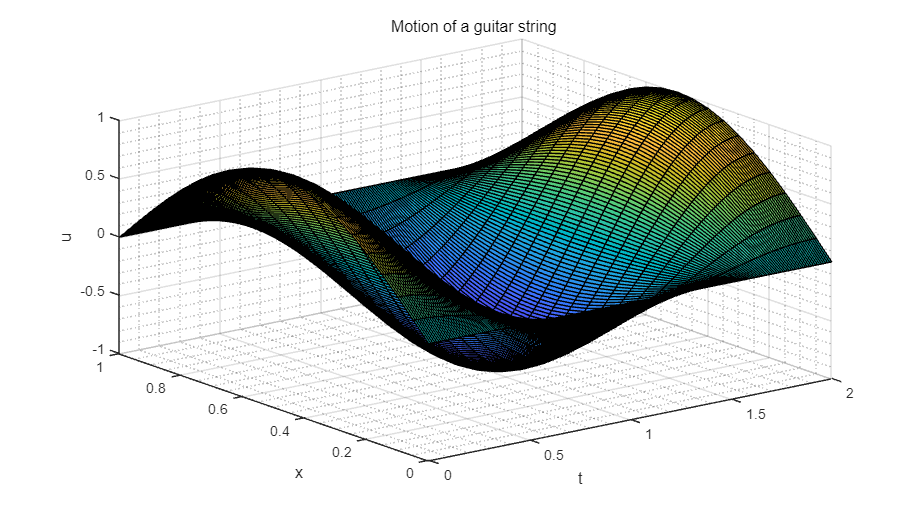

% For time step 0.01 and spatial grid spacing 0.05
% Housekeeping
clear
clc

% Define the basic parameters
c = 1;
L = 1;

t0 = 0; % define the initial time
tf = 2; % define the final time

x0 = 0;                   % define the initial x
xf = L;                   % define the final x
detx = 0.05;              % Δx
N = (xf - x0) / detx + 1; % number of discretised points
X = 0: detx: L;           % define X

h = 0.01; % define the stepsize

% Define initial condition
u01 = sin(pi* X);

u02 = zeros(length(X), 1);

u0 = [u01'; u02];

% Define the function
f = @(t, u) [u(N+1: end); 0; (c / detx) ^ 2 * gallery('tridiag', N-2, 1, -2, 1) * u(2: N-1); 0]; % u(1) = 0, from u(2) to u(N-1)

% Compute the numerical solution

[t, u] = RungeKutta4(f, t0, tf, u0, h);

% Plot the numerical solutions for angular velocity
surf(t, X, u(1: N, :));  % plot function

title('Motion of a guitar string ', FontSize = 15);

xlabel('t'); 
ylabel('x');
zlabel('u');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph

% For time step 0.01 and spatial grid spacing 0.05
% Housekeeping
clear
clc

% Define the basic parameters
c = 1;
L = 1;

t0 = 0; % define the initial time
tf = 2; % define the final time

x0 = 0;                   % define the initial x
xf = L;                   % define the final x
detx = 0.05;              % Δx
N = (xf - x0) / detx + 1; % number of discretised points
X = 0: detx: L;           % define X

h = 0.01; % define the stepsize

% Define initial condition
u01 = sin(pi* X);

u02 = zeros(length(X), 1);

u0 = [u01'; u02];

% Define the function
f = @(t, u) [u(N+1: end); 0; (c / detx) ^ 2 * gallery('tridiag', N-2, 1, -2, 1) * u(2: N-1); 0]; % u(1) = 0, from u(2) to u(N-1)

% Compute the numerical solution

[t, u] = RungeKutta4(f, t0, tf, u0, h);

% Plot the numerical solutions for angular velocity
surf(t, X, u(1: N, :));  % plot function

title('Motion of a guitar string ', FontSize = 15);

xlabel('t'); 
ylabel('x');
zlabel('u');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph

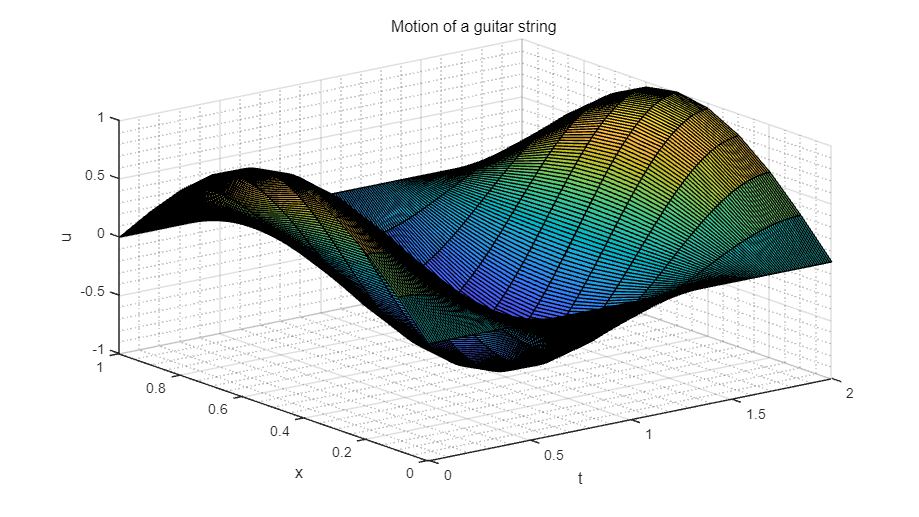

% For time step 0.01 and spatial grid spacing 0.1

% Housekeeping
clear
clc

% Define the basic parameters
c = 1;
L = 1;

t0 = 0; % define the initial time
tf = 2; % define the final time

x0 = 0;                   % define the initial x
xf = L;                   % define the final x
detx = 0.1;               % Δx
N = (xf - x0) / detx + 1; % number of discretised points
X = 0: detx: L;           % define X

h = 0.01; % define the stepsize

% Define initial condition
u01 = sin(pi* X);

u02 = zeros(length(X), 1);

u0 = [u01'; u02];

% Define the function
f = @(t, u) [u(N+1: end); 0; (c / detx) ^ 2 * gallery('tridiag', N-2, 1, -2, 1) * u(2: N-1); 0]; % u(1) = 0, from u(2) to u(N-1)

% Compute the numerical solution

[t, u] = RungeKutta4(f, t0, tf, u0, h);

% Plot the numerical solutions for angular velocity
surf(t, X, u(1: N, :));  % plot function

title('Motion of a guitar string ', FontSize = 15);

xlabel('t'); 
ylabel('x');
zlabel('u');
set(gca, 'FontSize', 12) % set the fontsize of the axis

grid minor;                            % set the grid of the graph

### Part II: Theoretical Considerations

#### Exercise 3

Consider the heat equation

∂u / ∂t = α ∂2u / ∂x2 ,

and its numerical solution using second order spatial differencing and explicit Euler for its time-advancement scheme.

1. Derive the modifed equation corresponding to this numerical scheme

2. Show that the accuracy of the scheme can be improved by selecting the spatial grid spacing Δx and the time step Δt such that

αΔt / Δx2 = 1 / 6.

% See written one

#### Exercise 4

Consider the heat equation

∂ϕ / ∂t = α ∂2ϕ / ∂x2 .

1. Derive the ODE which appriximates the heat equation if you perform a semidiscretization of the spatial variable x using second order central differencing.

2. Suppose you are to solve the system of ODEs obtained in part 1 of this question using the trapezoidal method. Using modified wavenumber analysis, show that the resulting numerical scheme is unconditionally stable.

% See written one